Reset the workspace

clc;
clear;
close all;
delete('*.mat');
delete('*.asv');
delete('*.avi');

Load the model.

robot_name = 'frankaEmikaPanda';
robot = loadrobot(robot_name, 'DataFormat', 'column');

Get the number of joints.

numJoints = numel(homeConfiguration(robot));

Specify the robot frame where the end-effector is attached.

endEffector = "panda_hand";

Specify initial and desired end-effector poses. Use inverse kinematics (maps from pose to joint angles) to solve for the initial robot configuration given a desired pose.

% 末端执行器位于机器人前方 0.5 m、高度 0.4 m 处，手爪朝下、x 轴反向（向后）、z 轴反向（向下）。
Xpos = 0.48;
Ypos = -0.2;
Zpos = 0.28;
T = trvec2tform([Xpos Ypos Zpos])

T =     1.0000         0         0    0.4800
         0    1.0000         0   -0.2000
         0         0    1.0000    0.2800
         0         0         0    1.0000



yaw = 0;    % 绕Z轴旋转0°
pitch = pi/2;  % 绕Y轴旋转180°
roll = 0;   % 绕X轴旋转0°
R = eul2rotm([yaw pitch roll], 'ZYX');

taskInit = T;
taskInit(1:3,1:3) = R;   % 替换旋转

% Compute current robot joint configuration using inverse kinematics
% 求机械臂逆解
ik = inverseKinematics('RigidBodyTree', robot);
ik.SolverParameters.AllowRandomRestart = false;
weights = [1 1 1 1 1 1];

% 输入ik的参数设置（指定末端关节，初始位置，权重，归位设置）
currentRobotJConfig = ik(endEffector, taskInit, weights, robot.homeConfiguration);

% The IK solver respects joint limits, but for those joints with infinite
% range, they must be wrapped to a finite range on the interval [-pi, pi].
% Since the the other joints are already bounded within this range, it is
% sufficient to simply call wrapToPi on the entire robot configuration
% rather than only on the joints with infinite range.
% 将无限旋转关节数据映射到[-pi,pi]的范围内，防止出错
currentRobotJConfig = wrapToPi(currentRobotJConfig);

% 末端执行器位于机器人前方 0.5 m、高度 0.4 m 处，手爪朝下、x 轴反向（向后）、z 轴反向（向下）。
Xposf = 0.65;
Yposf = 0.2;
Zposf = 0.58;
Tf = trvec2tform([Xposf Yposf Zposf])

Tf =     1.0000         0         0    0.6500
         0    1.0000         0    0.2000
         0         0    1.0000    0.5800
         0         0         0    1.0000



yawf = 0;    % 绕Z轴旋转0°
pitchf = pi/2;  % 绕Y轴旋转180°
rollf = 0;   % 绕X轴旋转0°
Rf = eul2rotm([yawf pitchf rollf], 'ZYX');

taskFinal = Tf;
taskFinal(1:3,1:3) = Rf;   % 替换旋转

anglesFinal = rotm2eul(taskFinal(1:3,1:3),'XYZ');
poseFinal = [taskFinal(1:3,4);anglesFinal']; % 6x1 vector for final pose: [x, y, z, phi, theta, psi]

% Final configuration
finalRobotJConfig = ik(endEffector, taskFinal, weights, currentRobotJConfig);
finalRobotJConfig = wrapToPi(finalRobotJConfig);

### 障碍物设置

下面的函数用于设置障碍物

creatCollisionBox

运行可视化，展示初始状态

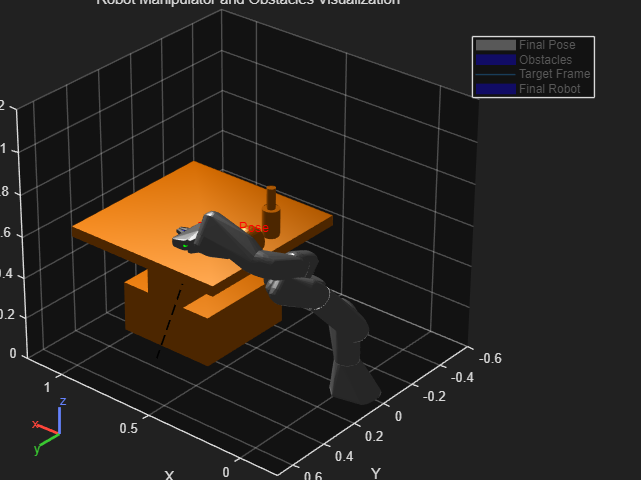

x0 = [currentRobotJConfig', zeros(1,numJoints)];
InitialVisualizer;

Specify a safety distance away from the obstacles. This value is used in the inequality constraint function of the nonlinear MPC controller.

safetyDistance = 0.05; 

STOMP实现部分

% helperSTOMP;